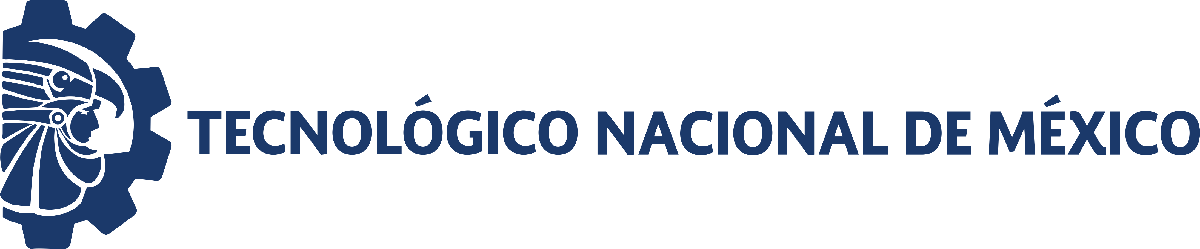                                 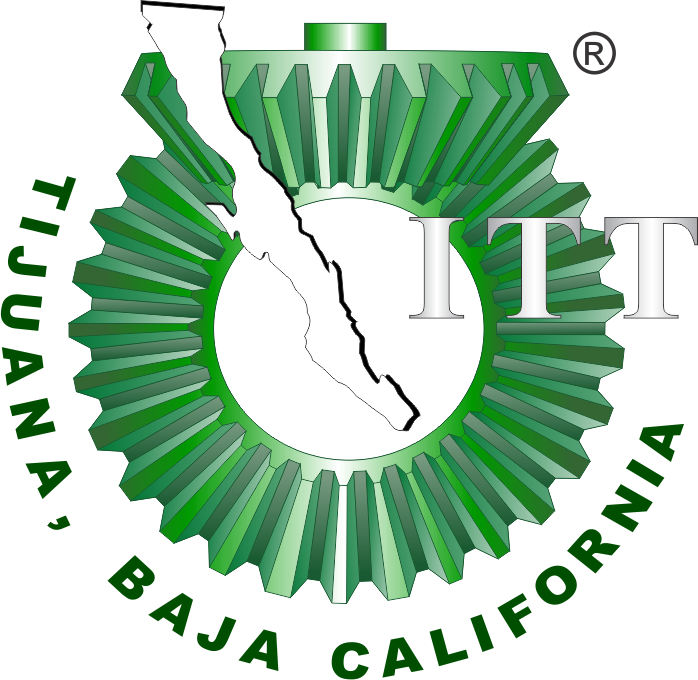

# Práctica: Regeneración de globulos rojos.

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

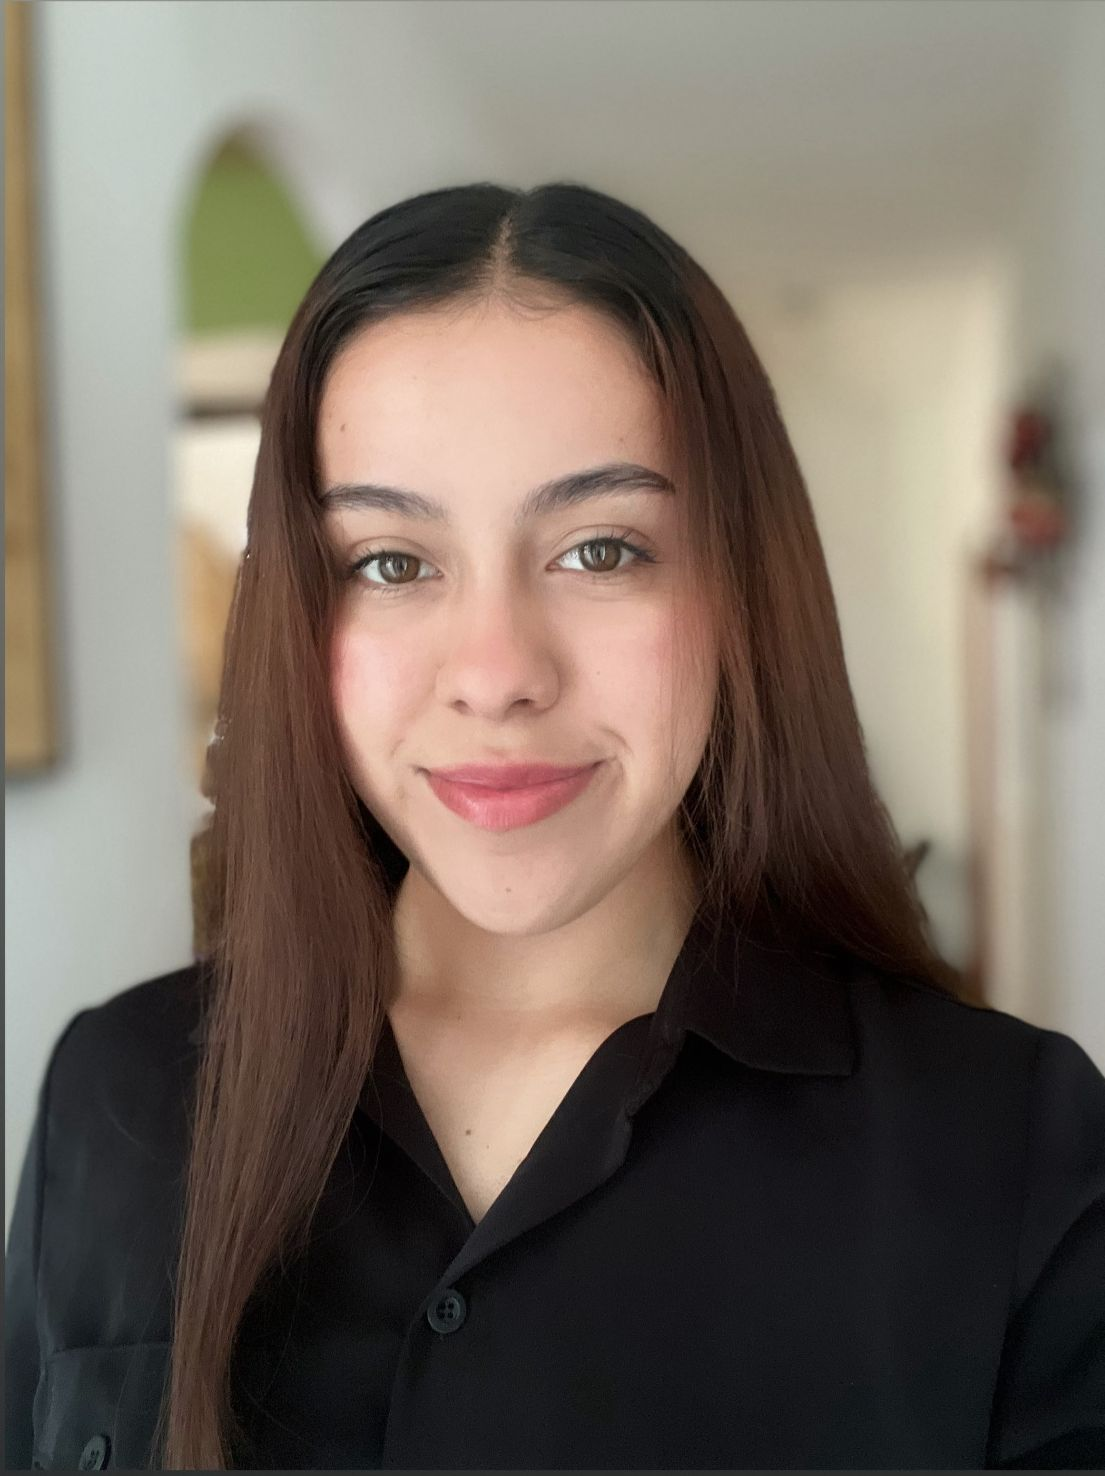

Nombre del alumno: Puentes Hernandez Yoseline Lizeth

Número de control: 22212265

Correo institucional: l22212265**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all')

tend=180; %tiempo de simulacion
dt=1E-3; %Intervalo para el metodo de solucion por diferencias finitas
n=round(tend/dt);%cantidad de iteraciones para el metodo numerico
%condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885;
%Parametros particulares para cada paciente
gamma = [0.769, 0.388, 0.510, 0.590,0.262, 0.324, 0.356, 0.089, 0.243, 0.057];
beta = [1.650,0.867,1.617,2.615,1.518,2.676,0.891,2.557,0.925,0.089];
%intrvalo para cond iniciales
xmin = 0.95; xmax=1.05;
seed=05211261; %semilla para asegurar reproducibilidad
rng(seed,'twister')
interval= xmin + (xmax-xmin).*rand(1,numel(gamma));
%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) ='); disp(x1_0);...
x2_0 = x2_0*interval; disp('x2(0) ='); disp(x2_0);...    
x3_0 = x3_0*interval; disp('x3(0) ='); disp(x3_0);...


x1(0) =
   57.2815   57.2456   57.7344   61.6576   59.1265   56.9357   58.2014   57.6006   58.2847   60.8827



x2(0) =
   42.7184   42.6916   43.0562   45.9820   44.0943   42.4605   43.4044   42.9564   43.4666   45.4040



x3(0) =
  859.2221  858.6837  866.0163  924.8643  886.8976  854.0354  873.0213  864.0086  874.2705  913.2401



## Caso: Con transfusion sanguinea

u =  zeros(n+1,1); u(1:1/dt)=1;
fig = 2;
for i =1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i),x3_0(i),beta(i), gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Sin transfusion sanguinea

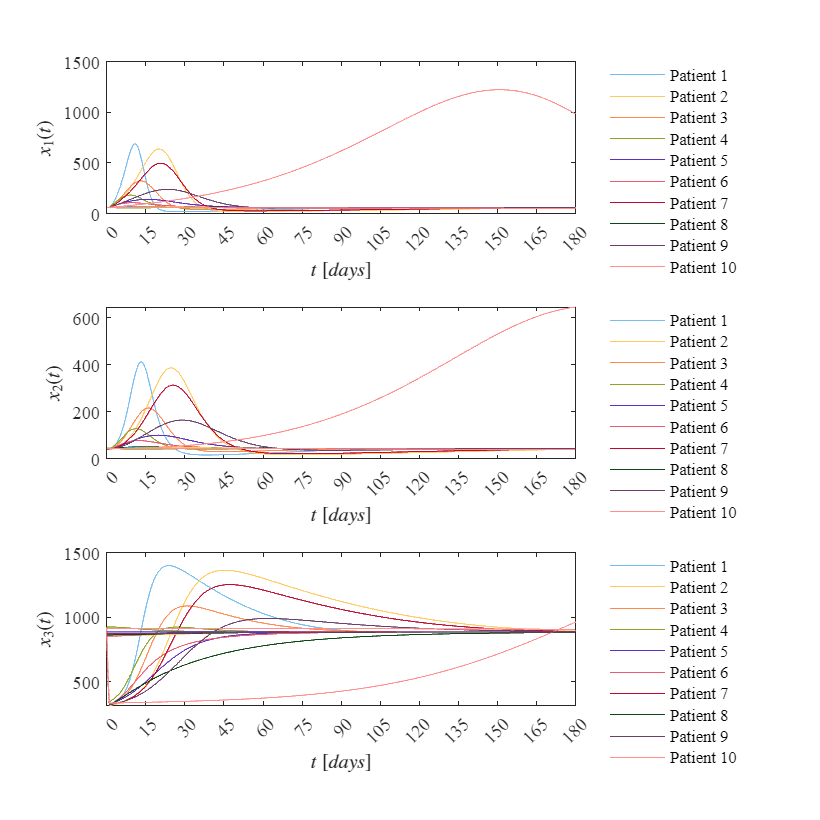

u = zeros(n+1,1);
fig = 1;
for i =1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i),x3_0(i),beta(i), gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Funciones

Modelo matematico

## 
$${\dot{X} }_1 =\beta \left(x_0 -k_{1\textrm{x1}} \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-\mu \left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$


## 
$${\dot{x} }_2 =\beta \left(k_{1\textrm{x1}} -k_{2\textrm{x2}} \right)$$


${\dot{x} }_3$ = $\beta \left(k_{2\textrm{x2}} -\alpha x_3 \right)-u\left(t\right)x_3$

function [t,x1,x2,x3]= system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%parametros fijos
Base= 885.42; X0=7.3785; k1= 0.125; k2= 0.1667; alpha=0.00833;
t= (0:dt:tend)';
n=round(tend/dt);
x1= zeros(n+1,1); x1(1) = x1_0;
x2= zeros(n+1,1); x2(1) = x2_0;
x3= zeros(n+1,1); x3(1) = x3_0;

for i=1:n
    x1(i+1)= x1(i)+ (beta*(X0-k1*x1(i))+gamma*(Base-x3(i))*(1-u(i))*x1(i)/Base)*dt;
    x2(i+1)= x2(i)+(beta*(k1*x1(i)-k2*x2(i)))*dt;
    x3(i+1)= x3(i)+(beta*(k2*x2(i)-alpha*x3(i))-u(i)*x3(i))*dt;
    end
end


## Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
    set (figure(fig),'color','w')
    set(gcf,'units','Centimeters','Position',[1,1,20,20])
mycolors = [119,190,240;
            255,203,97;
            255,137,79;
            138,166,036;
            092,047,194;
            234,091,111;
            191,009,047;
            013,071,021;
            107,063,105;
            255,143, 143]/255;
colororder(mycolors)
    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x1)
    xlabel('$t$ $[days]$','interpreter','latex','Fontsize',10)
    ylabel('$x_1(t)$','interpreter','latex','Fontsize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Timer New Roman','Fontsize',10)
    L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

    subplot(3,1,2)
    hold on; grid off; box on;colororder(mycolors);
    plot(t,x2)
    xlabel('$t$ $[days]$','interpreter','latex','Fontsize',10)
    ylabel('$x_2(t)$','interpreter','latex','Fontsize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Timer New Roman','Fontsize',10)
    L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

    subplot(3,1,3)
    hold on; grid off; box on;colororder(mycolors);
    plot(t,x3)
    xlabel('$t$ $[days]$','interpreter','latex','Fontsize',10)
    ylabel('$x_3(t)$','interpreter','latex','Fontsize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Timer New Roman','Fontsize',10)
    L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

if fig==1
    exportgraphics(gcf,'Caso sin transferencia.pdf','contentType','Vector')
    elseif fig==2
    exportgraphics(gcf,'Caso con transferencia.pdf','contentType','Vector')
     end
end